# IIR Digital Filters

## Introduction to IIR digital filters

Digital infinite impulse response (IIR) filter is defined by the following [ input $x(n)$$\rightarrow$ output $y(n)$] equation:


$$y(n) = \sum_{k=0}^{M} {b_{k}x(n-k)} - \sum_{k=1}^{N}{a_{k}y(n-k)} $$


An output sample $y(n)$ is the summation of two components:

- weighted average of last $M+1$ input samples $x(n-k)$, including the present one (the first sum),

- weighted average of $N$ last output samples $y(n-k)$, of course, without the actually computed (the second sum).

Below definition of the Z transform (ZT) is given and its relation with the discrete-time Fourier transform (DtFT):

**(ZT)**  $X(z)=\sum_{n=-\infty}^{+\infty}{x(n) (z)^{-n}}$   $\rightarrow$   $\left[ z=e^{j 2 \pi f/f_{s}} \right]$   $\rightarrow$   **(DtFT)**  $X(f)=\sum_{n=-\infty}^{+\infty} {x(n)  \left( e^{j 2 \pi f/f_{s}} \right) }^{-n}}$

ZT plays in digital world the same role as the Laplace transform in analog world. The Z transform has a very important for us feature:


$$Z \left( x(n-n_0) \right) = z^{-n_0}X(z)$},$$


 i.e. the ZT of signal delayed by $n_0$ samples is equal to the ZT of the original, not delayed signal, i.e. $X(z)$, multiplied by the $z^{-n_0}$. Thanks to this, after calculation of ZT of both sides of our first digital filtering input-output equation, we obtain the transfer function $H(z)$ of recursive digital filter IIR (pay attention that always $a_0=1$):

$H(z)=\frac{Y(z)}{X(z)}=\frac{{{b}_{0}}+{{b}_{1}}{{z}^{-1}}+{{b}_{2}}{{z}^{-2}}+...+{{b}_{M}}{{z}^{-M}}} {1+{{a}_{1}}{{z}^{-1}}+{{a}_{2}}{{z}^{-2}}+...+{{a}_{N}}{{z}^{-N}}} = \frac{ \left( 1-z_1z^{-1} \right)  \left( 1-z_1^*z^{-1} \right)  ... \left( 1-z_{M/2}z^{-1} \right)  \left( 1-z_{M/2}^*z^{-1} \right) } {\left( 1-p_{1}z^{-1} \right)  \left( 1-p_{1}^*z^{-1} \right)  ... {\left( 1-p_{M/2}z^{-1} \right)  \left( 1-p_{M/2}^*z^{-1} \right) }$,

where $z_k$ and $p_k$ are roots of the $H(z)$ nominator and denominator polynomials of $z^{-1}$. All zeros and poles occur in pairs: $\{ z_k, z_k^*\}$, $\{ p_k, p_k^*\}$ in order to obtain the $H(z)$ polynomials with real-value coefficients.

 Since DtFT is obtained from ZT after setting: $z=e^{j 2\pi f/f_{s}}$, we can deduce that the filter frequency response $H(f)$ is obtained from the filter transfer function $H(z) $ after the same setting: 


$$H(z) \quad \rightarrow \quad \left[ z=e^{j 2\pi f/f_s} \right] \quad \rightarrow \quad H(f)$$


where:

- $|H(f)|$ - is a magnitude (absolute value) of the filter frequency response (filter gain as a function of frequency),

- $\angle H(f)$- is an angle (phase shift) of the filter frequency response (filter phase delay/shift as a function of frequency, indirectly time delay).

**Example**.

*Filter input:*    $x(n)=A_0 \sin(2 \pi (f_0/f_{s}) n)$.

*Filter output:* $y(n)=(A_0 \cdot |H(f_0)|)  \cdot \sin(2 \pi (f_0/f_{s}) n+ \angle H(f_0)) =  (A_0 \cdot |H(f_0)|) \cdot \sin \left( 2 \pi (f_0/f_{s}) \left( n +  \frac {\angle H(f_0)}{2 \pi (f_0/f_{s})} \right) \right)$

i.e. $y(n)$ is equal to sinusoid having the same, input frequency, but scaled in amplitude by $|H(f_0)|$ and delayed by $\frac {\angle H(f_0)}{2 \pi (f_0/f_{s})}$ samples.

Due to weighted "averaging" of input and output samples (done by two summations present in the filter equation), the filter removes certain frequency components and is: low-pass (LP), high-pass (HP), band-pass (BP) and band-stop (BS). Selection of appropriate values of $b_k$ and $a_k$ is called a filter design while using them in weighted averaging of data  -  digital signal filtration.

**Analyze this Matlab code** as well as the code of the function `fun_figs_iir()` (at the end of this script). Run this program fragment. Modify values of a, b and observe change of: z, p and $|H(f)|$, $\angle H(f)$. Find what is the *filter gain* $|H(f)|$and the *filter phase shift* $\angle H(f)$ for input sinusoid having frequency $f_0 = 100$ Hz.

clear all; close all;

% Design of filter coefficients bk and ak
fs = 2000;                       % sampling frequency
f = 0 : 0.1 : fs/2;              % frequency interval of interest in hertz
b = [2, 3];                      % [ b0, b1 ] in H(z) nominator
a = [1, 0.2, 0.3, 0.4];          % [ a0=1, a2, a3, a4] in H(z) denominator
z = roots(b), p = roots(a),      % [b,a] --> [z,p]: coeffs --> roots

z = -1.5000

p =    0.2306 + 0.7428i
   0.2306 - 0.7428i
  -0.6612 + 0.0000i


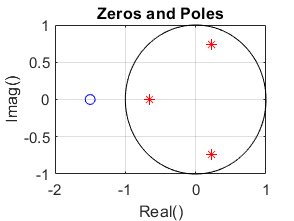

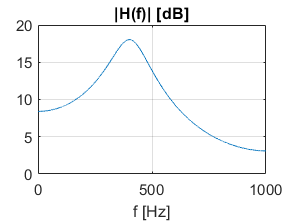

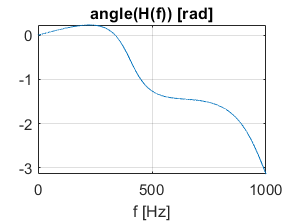

fun_figs_iir(b,a,z,p,f,fs);      % caling function for figure plotting

## IIR digital filter design by zeros & poles method

In "zeros and poles" IIR filter design method we are not selecting appropriate, real values of the TF polynomial coefficients $b_k$ and$a_k$ but complex values of $z_k$ and $p_k$ of the polynomial roots. We do their placement (always in conjugate pairs, similarly as in analog filters) but in respect to the unitary circle: $z=e^{j 2\pi f/f_{s}}, \;\; f \in [0,f_s]$. Figuratively speaking: frequency axis is "wrapped upon/around" the unitary circle (with radius = 1) and the angle/rotation of the $2\pi$ radians (360 degrees) corresponds to frequency change from 0 to $f_s$ hertz.

- Zero put on the circle is "zeroing" frequency, associated with the placement point.

- Pole put inside the circle, but close to it, is amplifying frequency associated with the closest point of the circle.

- Digital IIR filter is stable, when its poles lie in the circle interior (inside it) - position of zeros is arbitrary.

- The biggest advantage of the IIR filters is small number of coefficients $b_k$ and $a_k$which are required for ensuring a desired filter sharpness.

- The biggest disadvantages of the IIR filters are:  **1)** their design difficulty (risk of instability in fixed-point implementations characterized by limited computational precision), **2) **typically small non-linearity of their phase responses in the pass-band (resulting in different time delay of different frequency components on filter output, leading to change of shape of a signal passing through the filter).

**Become familiar with the Matlab code below**. We design an IIR filter which:

- attenuates frequencies 600 and 800 Hz (two zeros on the unitary circle, and their conjugations),

- amplifies frequencies 100 and 200 Hz (two poles inside the unitary circle but close to it, and their conjugations). 

Add one additional pair of zeros for additional removing the frequency 700 Hz, and one additional pair of poles for additional attenuation of frequency 300 Hz. Change number of zeros & poles and their values, and try to design a good low-pass filter having gain close to 1 in the frequency band [0,200] Hz  and high attenuation (e.g. gain=0.001) in the frequency band [400,fs/2]. 

% Design of zeros & poles of filter transfer function H(z)
% i.e. selection of TF polynomial roots
gain = 0.001;
z = [ 1,   1    ]  .* exp(j*2*pi*[ 600, 800 ]/fs);   z = [z conj(z)];  
p = [ 0.99, 0.99 ] .* exp(j*2*pi*[ 100, 200 ]/fs);   p = [p conj(p)];
b = gain*poly(z), a = poly(p),         % [z,p] --> [b,a]: roots --> coeffs

b =     0.0010    0.0022    0.0030    0.0022    0.0010


a =     1.0000   -3.4849    4.9766   -3.4156    0.9606


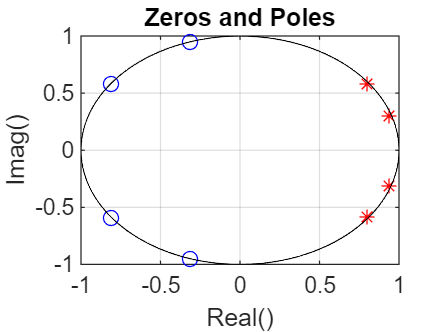

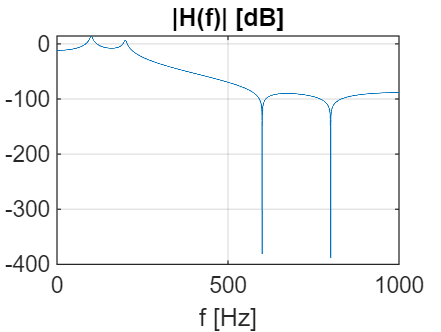

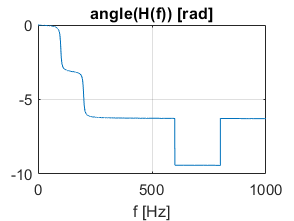

fun_figs_iir(b,a,z,p,f,fs);            % caling function for figure plotting

## IIR digital filter design by bilinear transformation of analog filters

Analog filters can be transformed to digital ones. There are several methods. We learn bilinear transformation only. Transfer function $H(s)$of analog filter is converted to transfer function $H(z) $ of digital filter using the following exchange of the variable $s$ (of the *analog* Laplace transform) with the variable $z$ (of the *digital* Z transfom):

$H(s) \quad \rightarrow \quad \left[ s=2 f_s \frac{z-1}{z+1} \right] \quad \rightarrow \quad H(z), \quad \text{where} \quad s=j 2 \pi f_a, \;\; z=e^{j 2 \pi f_d/f_s}$.

$f_d$ denotes some digital frequency while $f_a$ - corresponding analog frequency. Due to the transformation, polynomials of $s$ in analog filter transfer function $H(s)$are changed to polynomials of $z$ in digital filter $H(z)$. According to this equation:


$$(s-{{z}_{k}})=2{{f}_{s}}\frac{z-1}{z+1}-{{z}_{k}}=\left( 2{{f}_{s}}-{{z}_{k}} \right)\frac{z-\frac{2{{f}_{s}}+{{z}_{k}}}{2{{f}_{s}}-{{z}_{k}}}}{z+1},$$


each zero $z_k$ of the analog filter $H(s)$ is transformed into:

- one zero of the digital filter $H(z)$ (root of the nominator polynomial):  $$\frac{2{{f}_{s}}+{{z}_{k}}}{2{{f}_{s}}-{{z}_{k}}}$,

- one pole of the digital filter $H(z)$ (root of the denominator polynomial):  equal to "-1" ,

- additionally, due to the analog $z_k$, gain of the digital filter has to be multiplied by $(2f_s-z_k)$.

**Become familiar with the function  **`bilinearTZ()` given at the end.

Since the bilinear transformation is non-linear in frequency (it deforms the frequency axis), an analog filter to be converted to a digital one, has to be designed for different, "deformed*"*  analog frequencies $f_a$, resulting from desired digital frequencies $f_d$, namely for:

$f_a=2 f_s \cdot \tan \left( \pi \frac{f_d}{f_s} / (2 \pi) \right)$.

After transformation, the deformed analog frequencies are converted back to the requested digital frequencies (since cascade of any function and its inverse results in returning back to the starting point/value: $x=f(f^{-1}(x))$. 

**Analyze the Matlab code** below in which a digital bandpass IIR filter $H(z)$ is designed by means of bilinear transformation of specially designed analog filter $H(s)$. Again, have a look to the function `bilinearTZ()` (at this script end). Modify the program and design the high-pass digital IIR filter passing only frequencies in the band [200,fs/2] Hz OR the band-stop filter passing all frequencies except the range [300,500] Hz.

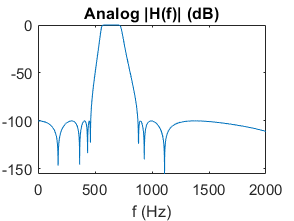

% Digital requirements
fs = 2000;         % sampling ratio
f1 = 400;          % minimum frequency of band-pass filter
f2 = 600;          % maximum frequency of band-pass filter
N  = 8;            % number of poles

% Analog requirements --> digital requirements
f1 = 2*fs*tan(pi*f1/fs) / (2*pi);     % f1: analog --> digital 
f2 = 2*fs*tan(pi*f2/fs) / (2*pi);     % f2: analog --> digital
w0 = 2*pi*sqrt(f1*f2);                % center of the pass-band 
dw = 2*pi*(f2-f1);                    % width of the pass-band

% Analog filter design (using different low-pass prototypes)
[z,p,gain] = cheb2ap(N,100);               % low-pass Chebyshev-2 prototype filter
[z,p,gain] = lp2bpTZ(z,p,gain,w0,dw);      % frequency transformation: LP to BP
b = real(gain*poly(z)); a = real(poly(p)); % analog zeros&poles --> [b,a] coeffs
f = 0 : fs/2000 : fs;                      % frequencies of interest
H = freqs(b,a,2*pi*f);                     % frequency response of analog filter
figure; plot(f,20*log10(abs(H))); xlabel('f (Hz)'); title('Analog |H(f)| (dB)'); 

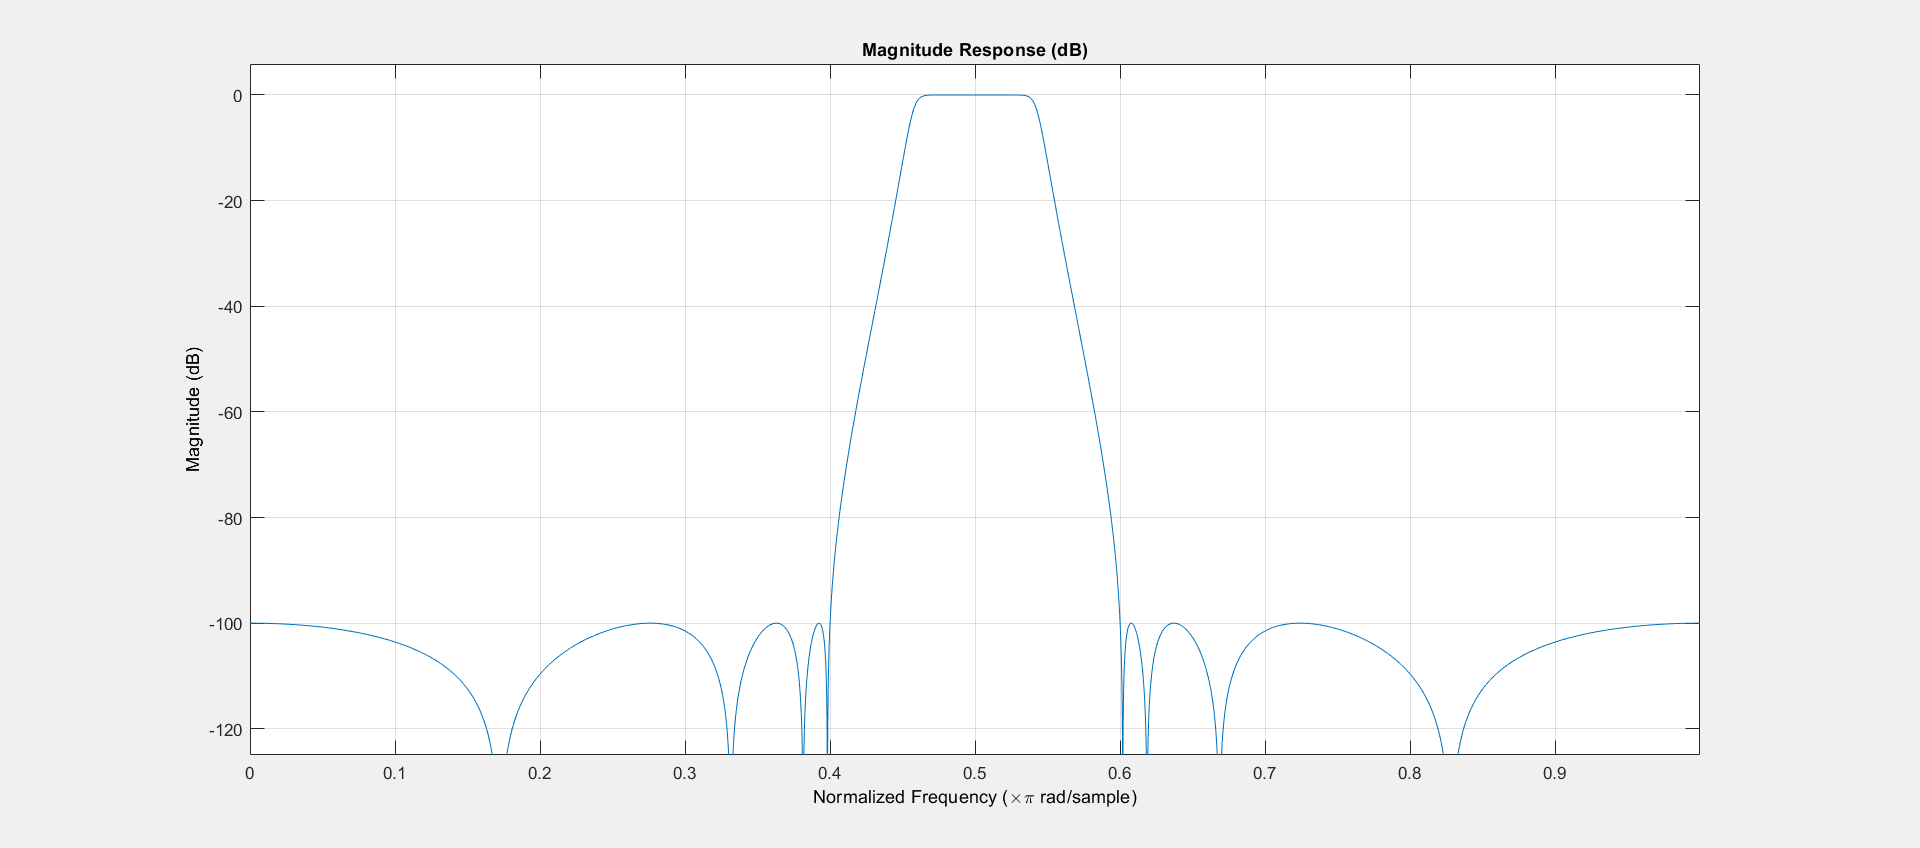


% Conversion of analog filter H(s) to digital filter H(z)
[z,p,gain] = bilinearTZ(z,p,gain,fs);      % bilinear transformation H(s) --> H(z)
b = real(gain*poly(z)); a = real(poly(p)); % digital zeros&poles --> [b,a] coeffs
fvtool(b,a),                               % displaying digital filter frequency response

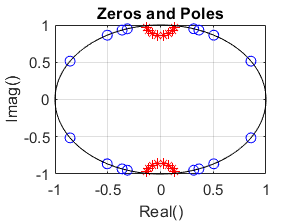

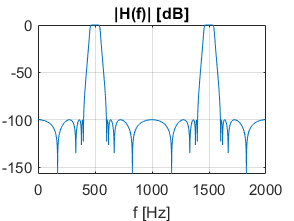

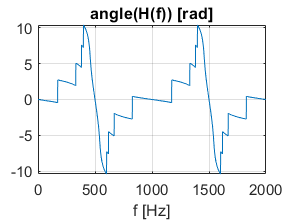


% Figures: zeros&poles position, filter frequency response
fun_figs_iir(b,a,z,p,f,fs);                % caling function for figure plotting

## IIR digital filtering

Finally, we will use one of designed digital IIR filters, i.e. we will write a Matlab code implementing the first equation of  this laboratory, i.e. the filter input-output relation: $x(n) \rightarrow [\text{filter}(b,a)] \rightarrow y(n)$.

**Analyze the Matlab code**. Run it.

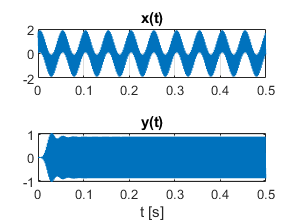

% Input signal x(n) - two sinusoids: 20 and 500 Hz
Nx = 1000;                                       % number of samples
dt = 1/fs; t = dt*(0:Nx-1);                      % sampling times
%x = zeros(1,Nx); x(1) = 1;                      % Kronecker delta impulse
x = sin(2*pi*20*t+pi/3) + sin(2*pi*500*t+pi/7);  % sum of 2 sines

% Digital IIR filtration: x(n) --> [ b, a ] --> y(n)
% y=filter(b,a,x);                               % all-in-one Matlab function
M = length(b);                                   % number of {b} coefficients
N = length(a); a = a(2:N); N=N-1;                % number of {a} coeffs, remove a0=1
bx = zeros(1,M);                                 % buffer for input samples x(n)
by = zeros(1,N);                                 % buffer for output samples y(n)
for n = 1 : Nx                                   % MAIN LOOP
    bx = [ x(n) bx(1:M-1) ];                     % put new x(n) into bx buffer
    y(n) = sum( bx .* b ) - sum( by .* a );      % do filtration, find y(n)
    by = [ y(n) by(1:N-1) ];                     % put y(n) into by buffer
end                                              % END LOOP

% FIGURES: comparison of input and output
figure;
subplot(211); plot(t,x); title('x(t)'); grid;    % input  signal x(t)
subplot(212); plot(t,y); title('y(t)'); grid;    % output signal y(t)
xlabel('t [s]');

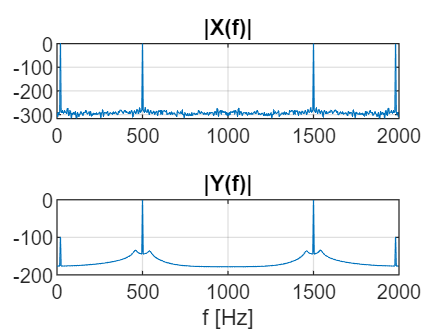

figure; % signal spectra of the second halves of samples (transients are removed!)
k=Nx/2+1:Nx;  f0 = fs/(Nx/2);  f=f0*(0:Nx/2-1); 
subplot(211); plot(f,20*log10(abs(2*fft(x(k)))/(Nx/2))); title('|X(f)|'); grid; 
subplot(212); plot(f,20*log10(abs(2*fft(y(k)))/(Nx/2))); title('|Y(f)|'); grid;
xlabel('f [Hz]');

## Matlab functions

Finally, test **ready-to-use Matlab functions**, for IIR digital filtering. What a wonderfull world!

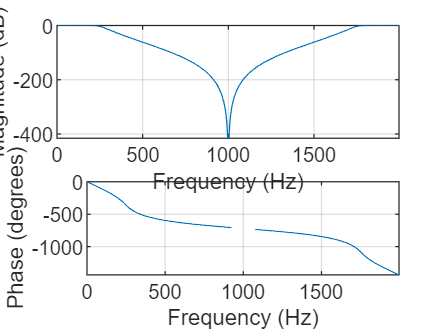

N = 8;                   % number of transfer function poles
f0=250; f1=400; f2=600;  % frequencies in Hz [1/s]
Rp = 3; Rs = 100;        % allowed ripples in dB in passband and stopband
  [b,a] = butter(N, f0/(fs/2), 'low');                   % Butt  LP 
% [b,a] = butter(N, f0/(fs/2), 'high');                  % Butt  HP
% [b,a] = butter(N, [f1,f2]/(fs/2), 'stop');             % Butt  BS
% [b,a] = butter(N, [f1,f2]/(fs/2), 'bandpass');         % Butt  BP
% [b,a] = cheby1(N, Rp, [f1,f2]/(fs/2), 'bandpass');     % Cheb1 BP
% [b,a] = cheby2(N, Rs, [f1,f2]/(fs/2), 'bandpass');     % Cheb2 BP
% [b,a] = ellip(N, Rp, Rs,[f1,f2]/(fs/2), 'bandpass');   % Ellip BP
freqz(b,a,f,fs);

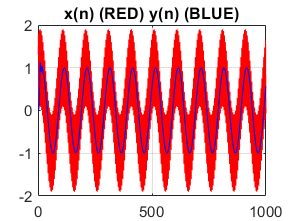

y = filter(b,a,x);
figure; plot(1:Nx,x,'r-',1:Nx,y,'b-'); grid; title('x(n) (RED) y(n) (BLUE)');

## Functions

function fun_figs_iir(b,a,z,p,f,fs)
% function for plotting figure describing the IIR digital filter H(z) 

% Displaying position of H(z) zeros and poles 
figure;
alpha = 0 : pi/1000 : 2*pi; c=cos(alpha); s=sin(alpha);
plot(real(z),imag(z),'bo', real(p),imag(p),'r*',c,s,'k-'); grid;
title('Zeros and Poles'); xlabel('Real()'); ylabel('Imag()');

% Displaying filter frequency responses: amplitude (gain), phase (time delay)
om = 2*pi*f/fs;                     % radial frequency
zz = exp(-j*om);                    % Z transform variable z^(-1)
H = polyval(b(end:-1:1),zz) ./ polyval( a(end:-1:1),zz); % ratio of two polynomials
% H = freqz(b,a,f,fs)                                    % all-in-one Matlab function
figure; plot(f,20*log10(abs(H))); xlabel('f [Hz]'); title('|H(f)| [dB]'); grid;
figure; plot(f,unwrap(angle(H))); xlabel('f [Hz]'); title('angle(H(f)) [rad]'); grid;
end

function [zz,pp,ggain] = bilinearTZ(z,p,gain,fs)
% Bilinear transformation: H(s) (analog filter) --> H(z) digital filter
% zeros, poles, gain (z,p,gain) --> zeros, poles, gain (zz,pp,ggain)

pp = []; zz = []; ggain = gain;
for  k=1:length(z)   % transforming "analog" zeros
     zz = [ zz (2*fs+z(k))/(2*fs-z(k)) ];
     ggain = ggain*(2*fs-z(k));
end
for  k=1:length(p)   % transforming "analog" poles
     pp = [ pp (2*fs+p(k))/(2*fs-p(k)) ];
     ggain = ggain/(2*fs-p(k));
end
if (length(p)>length(z)) zz = [ zz -1*ones(1,length(p)-length(z)) ]; end
if (length(p)<length(z)) pp = [ pp -1*ones(1,length(z)-length(p)) ]; end
end

function [zz,pp,gain] = lp2bpTZ(z,p,gain,w0,dw)
% LowPass to BandPass TZ

pp = []; zz = [];
for  k=1:length(z)  % transforming zeros of H(s)
     zz = [ zz roots([ 1 -z(k)*dw w0^2])' ];
     gain = gain/dw;
end
for  k=1:length(p)  % transforming poles of H(s)
     pp = [ pp roots([ 1 -p(k)*dw w0^2])' ];
     gain = gain*dw;
end
for k=1:(length(p)-length(z))
     zz = [ zz 0 ];
end

end